# Compressão de imagens com perdas através de transformada

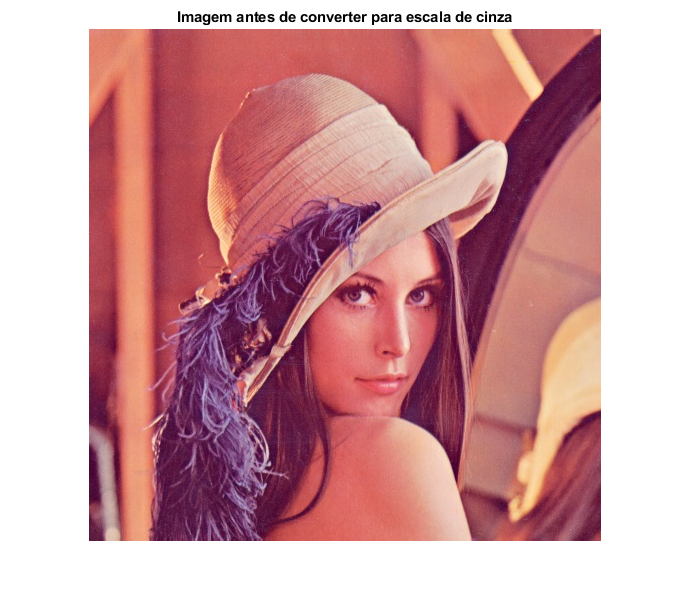

X = imread("Lenna.jpg");
imshow(X);title("Imagem antes de converter para escala de cinza");

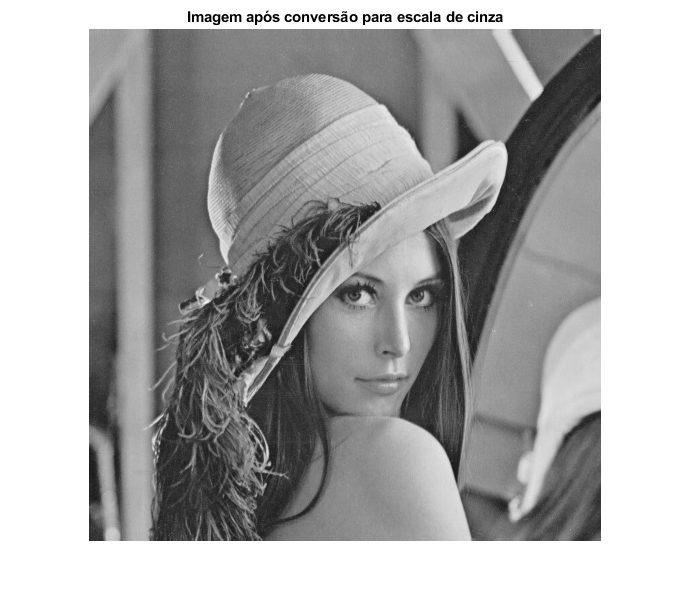

X = double(rgb2gray(X))/255;
imshow(X);title("Imagem após conversão para escala de cinza");

## Procedimentos para comprimir imagem

X_dct = dct2(X);
X_dct_modif = zeros(size(X_dct));
N = 512;
L = N; C = N;
L_final = round(0.5*L) ; C_final = round(0.5*C);
X_dct_modif(1:L_final,1:C_final) = X_dct(1:L_final,1:C_final);

## Procedimentos para recuperar imagem

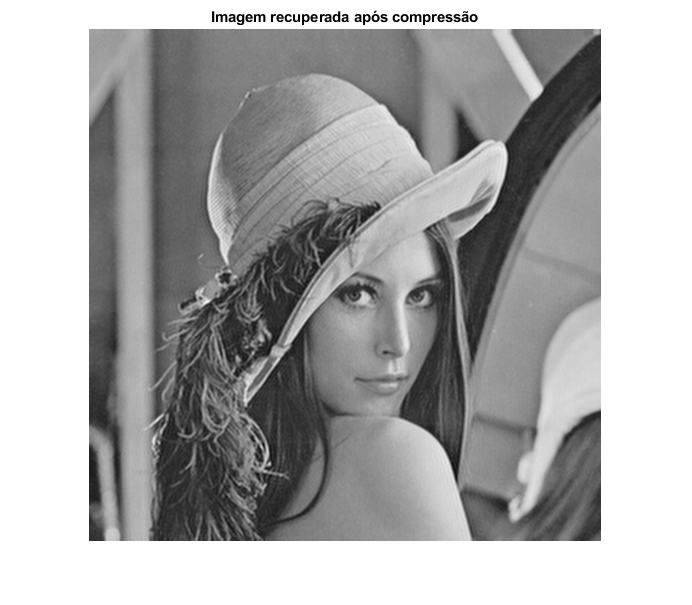

qtd_coeficientes = L_final*C_final;
fator_compressao = 1 - qtd_coeficientes/(L*C);
X_modif = idct2(X_dct_modif);
imshow(X_modif);title("Imagem recuperada após compressão");

Após a compressão com taxa de 75%,na recuperação foi possível notar que a imagem está muito próxima a original porém é possível perceber que houve perda de qualidade.

## Cálculo da relação sinal-ruído

MSE = (sum((X-X_modif).^2))/(sum(X).^2);

for(i = 1 : N)
    for(j = 1 : N)
        MSE_2 = ((X(i,j) - X_modif(i,j))^2)/((X(i,j))^2);
    end
end
MSE

MSE = 1.5145e-06

PSNR_db = 10*log10(65025/MSE)

PSNR_db = 106.3282

MSE_2

MSE_2 = 4.8184e-05

PSNR_db2 = 10*log10(65025/MSE_2)

PSNR_db2 = 91.3018